# Neurotechnology, Brains and Machines: Week 1

Sam Michalka

Much of this should be attributed to *Statistics in MATLAB: A Primer* by MoonJung Cho and Wendy L. Martinez.

Chapters 1-3 (mostly 3) should be an excellent reference for this notebook.

# Intro to Live Editor 

This document introduces you to using Live Editor, walks you through some examples, and contains exercises to complete. I strongly suggest using MATLAB 2016b or later. Like Mathematica and jupyter/python, MATLAB offers a notebook format (.mlx), which is what is open here. The notebook function (Live Editor) allows you to write text in a fancier format than your already beautiflly commented code. 


$$Keeping\; things\; \frac{voltage}{resistance} requires\; \Delta$$


Blue lines separate sections. Text has a white background (or blue if your cursor is in that section). Code has a gray background. You can execute this code by using the "Run Section" button on the top right in the "Live Editor" tab. Or you can press Ctrl+Enter (in Windows).

answertotheultimatequestion = 42

answertotheultimatequestion = 42

This is text that could have been describing the imaginary number below.

u = 1i; %Semicolons suppress output (which is important with large matrices)

You can use Alt+Enter to toggle between text and code.

thisiscode = 4*u %And you can comment without suppressing (or write your comments in the text area... but write them)

thisiscode = 0.0000 + 4.0000i

You can even insert images... like this one that shows you how to toggle between outputs below your code or outputs to the right side of your code.

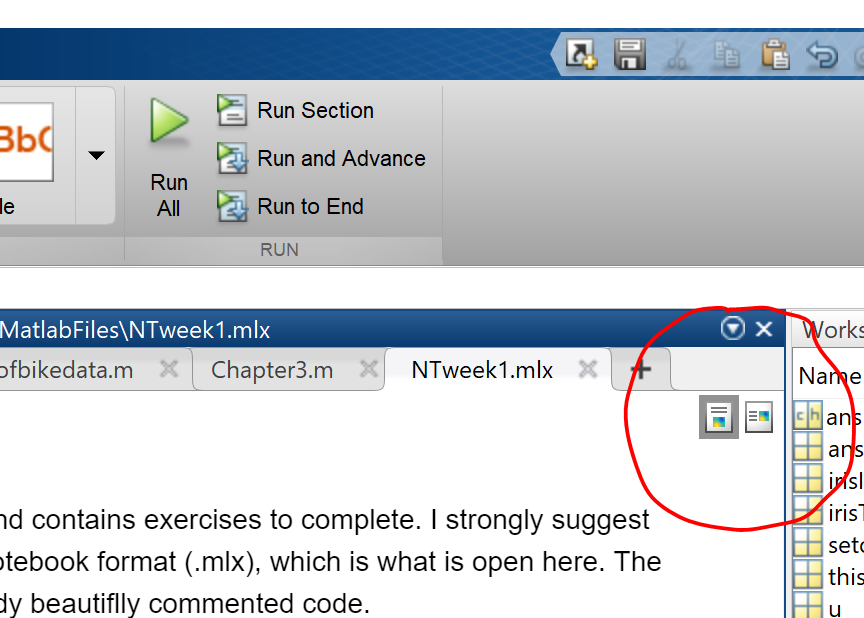

Finally, you can make a Section Break by hitting Ctrl+Alt+Enter.

# Loading and configuring data

Let's start by loading some data that is commonly used for analysis examples.  

The data set consists of observations of three species of iris: Iris setosa, Iris virginica, and Iris versicolor. There are 50 observations for each species with 4 measurements—sepal length and width, petal length and width—in centimeters (in that order as columns). They were originally collected by Anderson in 1935 [Anderson, 1935] and were subsequently analyzed by Fisher in 1936 [Fisher, 1936].  (image source: https://rstudio-pubs-static.s3.amazonaws.com/202738_7cad2477d76b4acc82b44244f94ccfa8.html#/1)

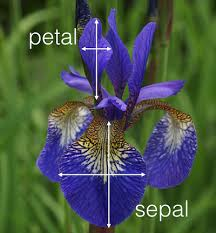

clear answertotheultimatequestion u thisiscode; % You can clear specific variables by calling their names or just use to "clear" to clear them all
load fisheriris.mat

Check your workspace to make sure that there are two variables.

whos

  Name           Size            Bytes  Class     Attributes

  meas         150x4              4800  double              
  species      150x1             19300  cell                



## **Tables**

Tables allow you to store data organized with observations as rows and variables as columns. The table format enforces that all the data for a variable are the same data type, such as strings, doubles, ints, etc. (Tables are similar to dataframes in pandas for python users.)

Details here: [https://www.mathworks.com/help/matlab/matlab_prog/advantages-of-using-tables.html](https://www.mathworks.com/help/matlab/matlab_prog/advantages-of-using-tables.html)

For this simple data set, there may not be a distinct advantage to storing our data in a table.  For the sake of getting our heads around tables, we will look at these analysis using both tables and our 3 array variables (setosa, versicolor, and virginica).

% Make a table called irises from an array of our stacked arrays of our 3 species.
iris = table(meas(:,1),meas(:,2),meas(:,3),meas(:,4),categorical(species))

iris = 150×5 table
    Var1    Var2    Var3    Var4     Var5 
    ____    ____    ____    ____    ______

    5.1     3.5     1.4     0.2     setosa
    4.9       3     1.4     0.2     setosa
    4.7     3.2     1.3     0.2     setosa
    4.6     3.1     1.5     0.2     setosa
      5     3.6     1.4     0.2     setosa
    5.4     3.9     1.7     0.4     setosa
    4.6     3.4     1.4     0.3     setosa
      5     3.4     1.5     0.2     setosa
    4.4     2.9     1.4     0.2     setosa
    4.9     3.1     1.5     0.1     setosa
    5.4     3.7     1.5     0.2     setosa
    4.8     3.4     1.6     0.2     setosa
    4.8       3     1.4     0.1     setosa
    4.3       3     1.1     0.1     setosa
    5.8       4     1.2     0.2     setosa
    5.7     4.4     1.5     0.4     setosa


iris.Properties.VariableNames{1} = 'sepallength';
iris.Properties.VariableNames{2} = 'sepalwidth';
iris.Properties.VariableNames{3} = 'petallength';
iris.Properties.VariableNames{4} = 'petalwidth';
iris.Properties.VariableNames{5} = 'species';
iris

iris = 150×5 table
    sepallength    sepalwidth    petallength    petalwidth    species
    ___________    __________    ___________    __________    _______

        5.1           3.5            1.4           0.2        setosa 
        4.9             3            1.4           0.2        setosa 
        4.7           3.2            1.3           0.2        setosa 
        4.6           3.1            1.5           0.2        setosa 
          5           3.6            1.4           0.2        setosa 
        5.4           3.9            1.7           0.4        setosa 
        4.6           3.4            1.4           0.3        setosa 
          5           3.4            1.5           0.2        setosa 
        4.4           2.9            1.4           0.2        setosa 
        4.9           3.1            1.5

# Loading the assignment 1 data

The data for this tutorial is a .mat format. However, you might want to load data from a text or csv file into a table. Here's how:

%readtable('Parkinsons.txt') % you need to delete the first % to uncomment

# Use histograms and boxplots to get a quick sense of your data

Create a histogram of the Sepal Length 

h = histogram(iris.sepallength) % Unsuppressed so you can see some of the properties

h =   Histogram with properties:

             Data: [150×1 double]
           Values: [4 18 30 31 32 22 7 6]
          NumBins: 8
         BinEdges: [4 4.5000 5 5.5000 6 6.5000 7 7.5000 8]
         BinWidth: 0.5000
        BinLimits: [4 8]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


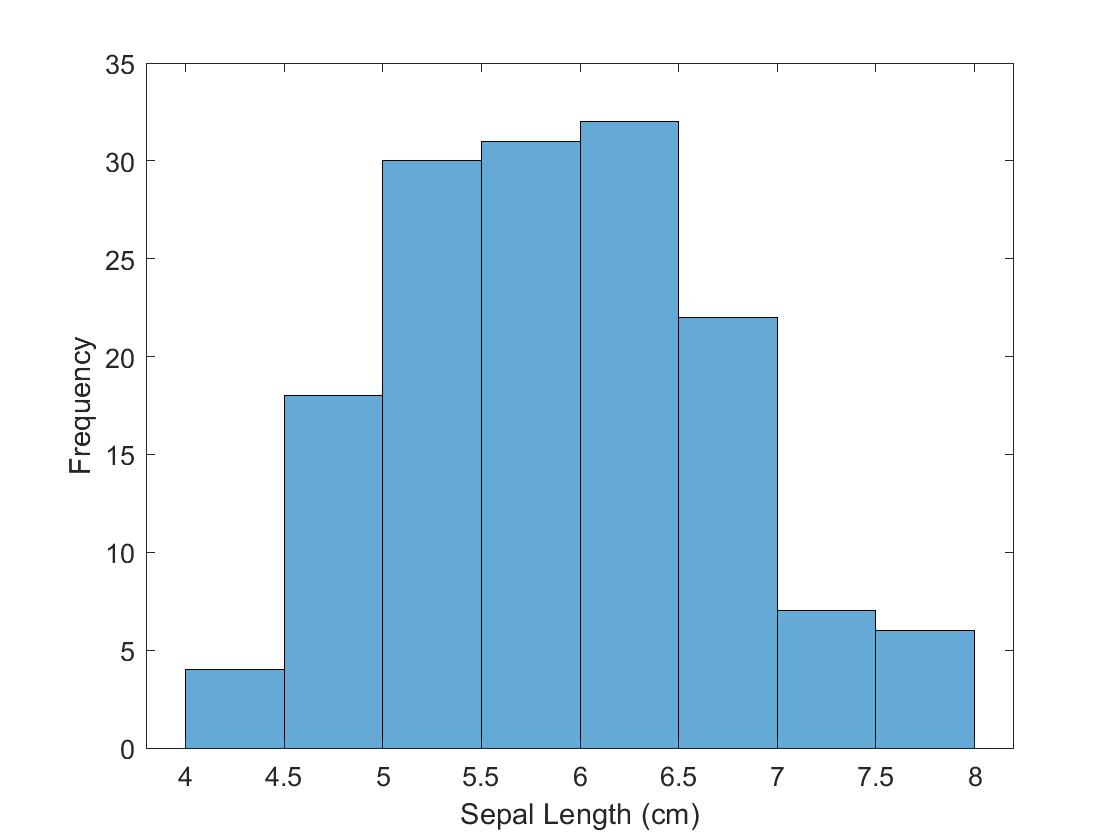

xlabel('Sepal Length (cm)'); ylabel('Frequency');

h = histogram(iris.species) % Unsuppressed so you can see some of the properties

h =   Histogram with properties:

              Data: [150×1 categorical]
            Values: [50 50 50]
    NumDisplayBins: 3
        Categories: {'setosa'  'versicolor'  'virginica'}
      DisplayOrder: 'data'
     Normalization: 'count'
      DisplayStyle: 'bar'
         FaceColor: 'auto'
         EdgeColor: [0 0 0]

  Show all properties


speciesnames = h.Categories

speciesnames = 1×3 cell array
    {'setosa'}    {'versicolor'}    {'virginica'}


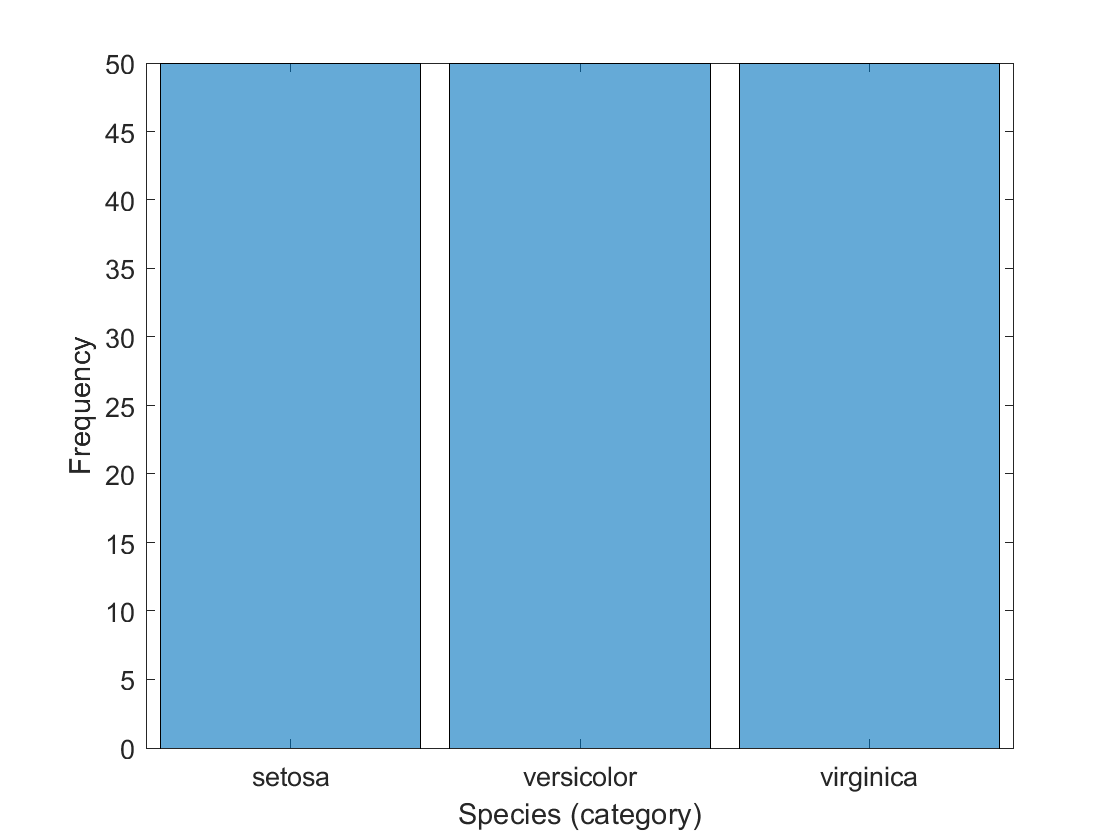

xlabel('Species (category)'); ylabel('Frequency');

Let's talk about about how to choose a subset of the data to do something with. This is called indexing.

iris(iris.species=='setosa',:)

ans = 50×5 table
    sepallength    sepalwidth    petallength    petalwidth    species
    ___________    __________    ___________    __________    _______

        5.1           3.5            1.4           0.2        setosa 
        4.9             3            1.4           0.2        setosa 
        4.7           3.2            1.3           0.2        setosa 
        4.6           3.1            1.5           0.2        setosa 
          5           3.6            1.4           0.2        setosa 
        5.4           3.9            1.7           0.4        setosa 
        4.6           3.4            1.4           0.3        setosa 
          5           3.4            1.5           0.2        setosa 
        4.4           2.9            1.4           0.2        setosa 
        4.9           3.1            1.5  


a = iris.sepallength(iris.species=='setosa')

a =     5.1000
    4.9000
    4.7000
    4.6000
    5.0000
    5.4000
    4.6000
    5.0000
    4.4000
    4.9000


b = iris(iris.species=='setosa','sepallength')

b = 50×1 table
    sepallength
    ___________

        5.1    
        4.9    
        4.7    
        4.6    
          5    
        5.4    
        4.6    
          5    
        4.4    
        4.9    
        5.4    
        4.8    
        4.8    
        4.3    
        5.8    
        5.7    


Plot a histogram of sepal length for each species on the same figure

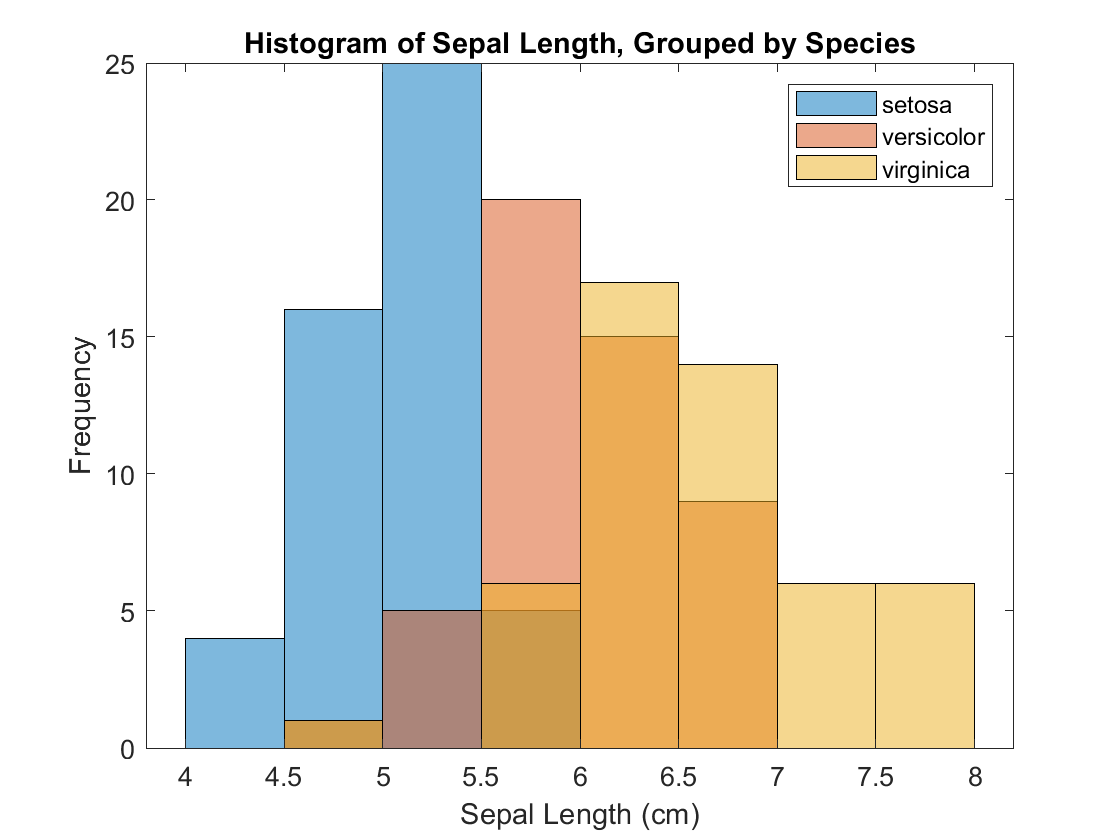

figure
binwidth = 0.2; %Since multiple histograms, we want to align the bin widths
facealpha = 0.5; %transparency of fill colors: 0 to 1
h1 = histogram(iris.sepallength(iris.species=='setosa'),'BinWidth',binwidth,'FaceAlpha',facealpha);
hold on; %make them on the same plot
h2 = histogram(iris.sepallength(iris.species=='versicolor'),'BinWidth',binwidth,'FaceAlpha',facealpha);
h3 = histogram(iris.sepallength(iris.species=='virginica'),'BinWidth',binwidth,'FaceAlpha',facealpha);
ylabel('Frequency'); xlabel('Sepal Length (cm)'); title('Histogram of Sepal Length, Grouped by Species');
legend({'setosa','versicolor','virginica'}); hold off; %Make sure to use hold off, or you'll end up with weird things in your other plots.

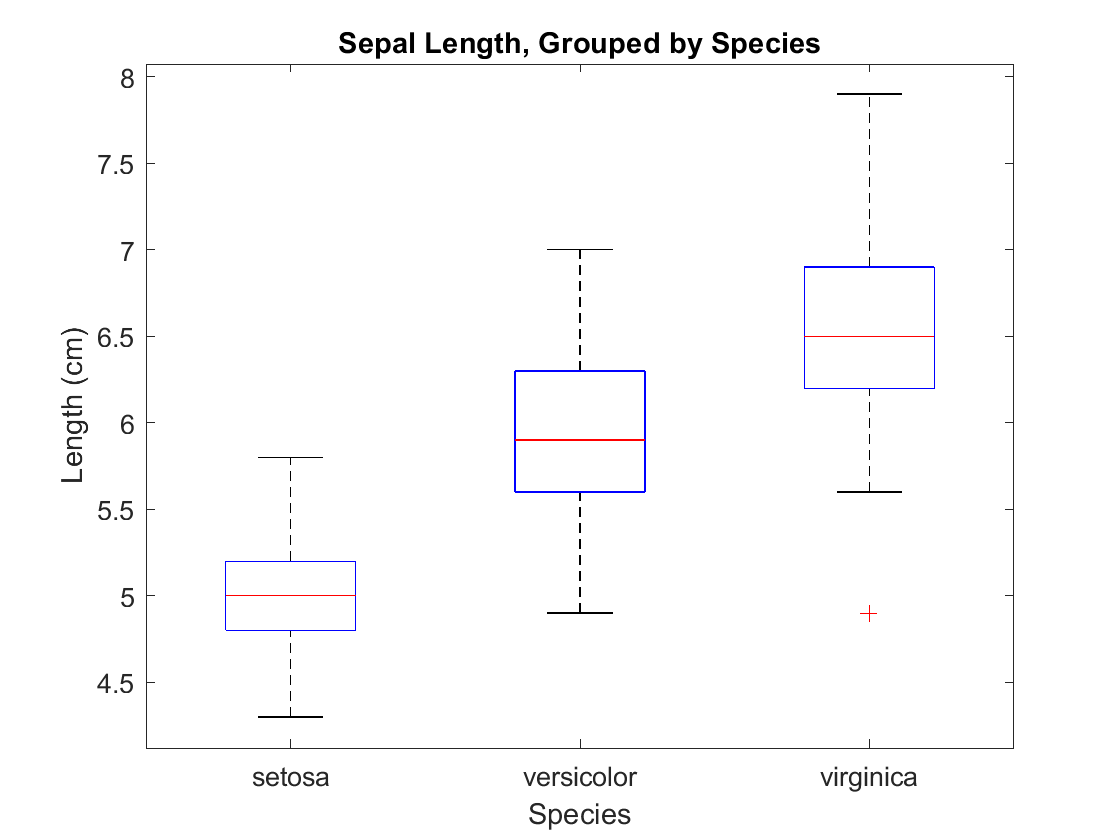

boxplot(iris.sepallength,iris.species); title('Sepal Length, Grouped by Species'); xlabel('Species'); ylabel('Length (cm)');

boxplot(iris.sepallength,iris.species); title('Sepal Length, Grouped by Species'); xlabel('Species'); ylabel('Length (cm)');

# Summary statistics

Tables allow you to instantly pull summary statistics of interest.  Keep in mind that these statistics are for all of the iris species combined.

summary(iris)


Variables:

    sepallength: 150×1 double

        Values:

            Min            4.3     
            Median         5.8     
            Max            7.9     

    sepalwidth: 150×1 double

        Values:

            Min             2     
            Median          3     
            Max           4.4     

    petallength: 150×1 double

        Values:

            Min              1     
            Median        4.35     
            Max            6.9     

    petalwidth: 150×1 double

        Values:

            Min           0.1     
            Median        1.3     
            Max           2.5     

    species: 150×1 categorical

        Values:

            setosa           50    
            versicolor       50    
            virginica        50    



**Exercise: Using the 3 arrays that we originally loaded (instead of the table), verify that the ****pedal width**** for all species combined matches the min, max, and median displayed by summary().**

% Answer code goes here

**Exercise: Create a histogram and a boxplot of the pedal width for all species combined. For the histogram, set the number of bins to 15.  **

Label your axes where appropriate. You can use the data in table or array format.  Confirm that your values above for the min, median, and max correspond to the appropriate lines on the box plot

% Answer code goes here



***Super important note about tables: ***Tables are a class in MATLAB that include labels and other metadata. Often functions (like mean) are looking for extracted data or arrays. To get this, make sure you use curly brackets to index your table (if you get an error, this might be your issue). If you index with regular parentheses, the output will be a table. This page has really good details: [https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html#zmw57dd0e25892](https://www.mathworks.com/help/matlab/matlab_prog/access-data-in-a-table.html#zmw57dd0e25892)

iris(1:3,2) %table
class(iris(1:3,2))
iris{1:3,2} %extracted data
class(iris{1:3,2})
iris{1:3,'sepalwidth'} % You can also select columns with their name

We can index the table to choose a subset of the data, such as just the "setosa" species.

rows = (iris.species == 'setosa'); %We can do this because species is a categorical varaible/class. Otherwise, we would need to use strcmp()
mean(iris.sepalwidth(rows)) 
% Or an alternative way to index, whatever floats your boat.
mean(iris{rows,'sepalwidth'})

Or you can summarize for each of the species using varfun and GroupingVariables

varfun(@mean,iris,'InputVariables','sepalwidth','GroupingVariables','species')

**Exercise: Verify the me****ans for each species using the array variables **

% Answer code goes here

**Exercise: Using the table data, create a histogram of the ****sepal length**** of the ****virginica**** species.  **

**Add a solid green ('g-') vertical line at the mean. **

**Add a dashed magenta ('m--') vertical line at the median. **

**Add a dotted blue ('b:') vertical line at the trimmed mean, excluding 30% of values (15% off each end).**

Don't forget to use "hold on" and "hold off". This code will create a green dashed vertical line at "val":

plot([val val],[0 20],'g--','LineWidth',2)

If you use h=histogram(put stuff in here), then you can use to automatically scale these lines:

plot([val val],[0 (5+max(h.Values))],'g--','LineWidth',2)

%Answer code goes here


**Exercise: Repeat the same plot above for 'mydata', given below.**

**Briefly discuss (in words) on the effects of the outliers on the mean, median, and trimmed mean.**

You will need to change the values in plot from 20 to 250 to get a good line.

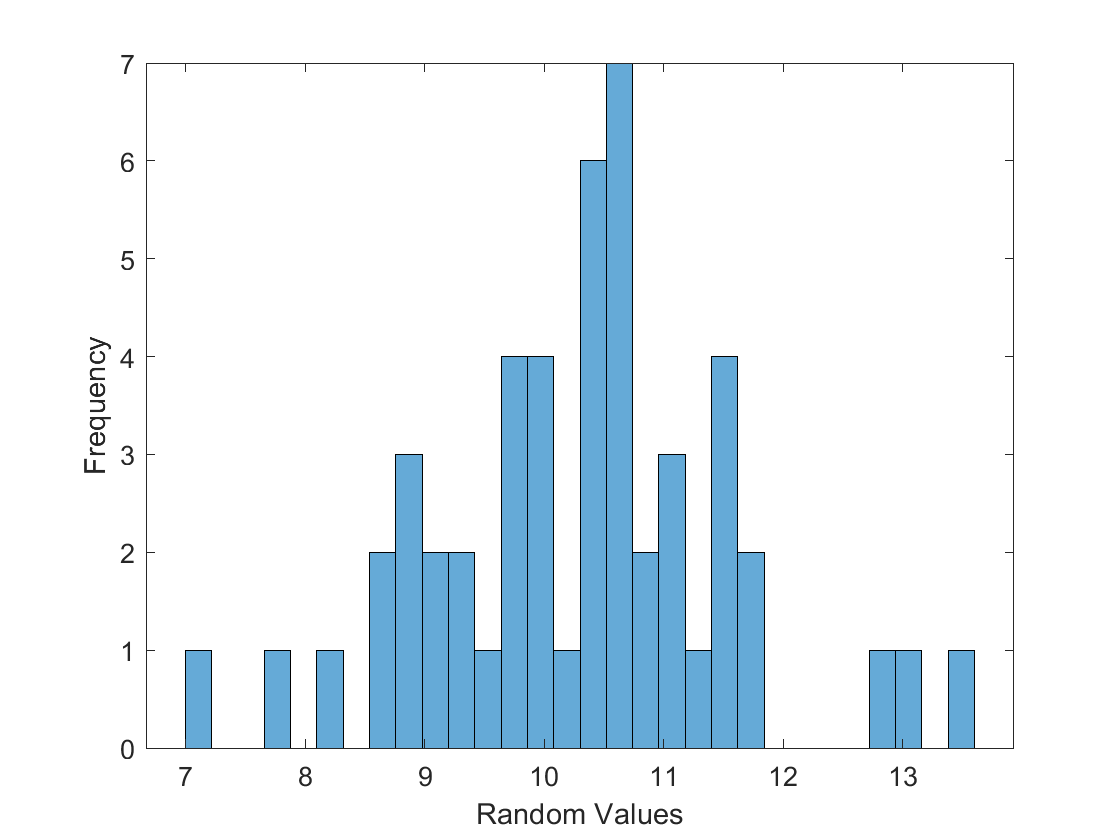

rval = rng('default');%Don't worry about this, just configuring things about random number generator
mydata = random('Normal',10,1,1,50);
%Uncomment the line below to look at the effect of outliers
%mydata(end-1:end) = [94 87]; %Change the last values to outliers.


h = histogram(mydata,30); hold on;
% Answer code goes here
%plot([PUT VALUES HERE],[0 (5+max(h.Values))],'g-','LineWidth',2);
%plot([PUT VALUES HERE],[0 (5+max(h.Values))],'m--','LineWidth',2);
%plot([PUT VALUES HERE],[0 (5+max(h.Values))],'b:','LineWidth',2); hold off
xlabel('Random Values'); ylabel('Frequency');

*Answer text goes here.*

# Measures of dispersion

Variance, standard deviation, mean absolute deviation, range, interquartile range

mydata = random('Normal',10,1,1,50);
%Uncomment the line below to look at the effect of outliers
%mydata(end-1:end) = [94 87]; %Change the last values to outliers.

var(mydata) %variance (specifically sample variance, which uses n-1)

ans = 1.0831

std(mydata) %sample standard deviation 

ans = 1.0407

sqrt(var(mydata)) % standard deviation is the square root of the variance

ans = 1.0407

quantile(mydata,[.25 .50 .75]) %the middle value should be the median

ans =     9.1955    9.9553   10.6966


iqr(mydata) %interquartile range, should related to the quantile outputs (value for .75 - value for .25)

ans = 1.5011


mad(mydata) %mean absolute deviation

ans = 0.8269

**Exercise: Briefly discuss the differences between the standard deviation, mean absolute deviation, and interquartile range.  Note the effect of outliers on these measures (which are robust to outliers?).**

*Answer text goes here*

**Exercise: Write code using the mathematical formula to calculate the sample standard deviation of mydata and confirm this is matches the value from std()**

% Answer code goes here


**Exercise: Make a histogram of mydata (no outliers) and include vertical lines at the mean (green), +/- 1 standard deviation from the mean (cyan, 'c'), +/- 2 standard deviations from the mean (blue)**

% Answer code goes here

# Correlation and Covariance

Section 3.2.3 in Statistics in Matlab: A Primer discusses correlation and covariance and my be a useful reference.  In general, correlation and covariance are used to describe relationships between variables.

Let's return to our iris data, stored in the table named iris.

Calculate the covariance matrix for the petal lengh and petal width of all species of irises.

cv = cov(iris.petallength,iris.petalwidth)

The value of cv(1,1) is the variance of the petal lengths. And the value of cv(2,2) is the variance of the petal widths.

var(iris.petallength)
var(iris.petalwidth) == cv(2,2)  %This is a way to test if a statement is true (make sure to use ==, no just =). 1 is true, 0 is false

The covarance between petal length and width is found off the diagonal in cv(1,2) and cv(2,1).  Note that the covariance matrix is symmetric.

We can plot these two variables in relation to each other.

plot(iris.petallength,iris.petalwidth,'o'); xlabel('Petal Length (cm)'); ylabel('Petal Width (cm)');

 The plotmatrix function is a nice way to visualize both the histograms of single variables and the relationships between the varaibles (though the labeling requires some extra work, at least is r2016b). 

figure;
[~,AX] = plotmatrix(iris{:,3:4});  
AX(1,1).YLabel.String = 'Petal Length';
AX(2,1).YLabel.String = 'Petal Width';
AX(2,1).XLabel.String = 'Petal Length';
AX(2,2).XLabel.String = 'Petal Width';


You can also generate a covariance matrix using a single array, where each row is an observation and each column is a variable (sounds a lot like the data we extract from a table).

cvall = cov(iris{:,1:4})
colnames = iris.Properties.VariableNames(1:4) %also extract the corresponding variable/column names

**Exercise: Find the covariance between the sepal width and petal width, both by indexing in cvall and by calling the cov() function.**

% Answer code goes here


The correlation coefficient can be calculated in a similar way. Note that the correlation coefficient is bound between -1 and +1.

crall = corrcoef(iris{:,1:4})

It is often valuable to visualize the covariance and/or correlation matrices.  Note the values in the colorbar legend

imagesc(cvall); colorbar; axis square; title('Covariance Matrix of Iris Characterisitics')
set(gca,'XTick',1:4, 'XTickLabel',colnames,'XTickLabelRotation',45,...
'YTick',1:4, 'YTickLabel',colnames)
figure
imagesc(crall); colorbar; axis square; title('Correlation Matrix of Iris Characterisitics')
set(gca,'XTick',1:4, 'XTickLabel',colnames,'XTickLabelRotation',45,...
'YTick',1:4, 'YTickLabel',colnames)

**Exercise: Briefly discuss the relationship between covariance and correlation. Give examples of when you might use one measurement over the other.**

*Answer text goes here*

# Quick starter for the assignment

data = readtable('Parkinsons.txt')

data = 526×5 table
    age    PStype     PSS      actual    screen
    ___    ______    ______    ______    ______

    88     'ES'      66.145      0         0   
    69     'ES'      64.896      0         0   
    65     'PSI'     70.863      1         0   
    89     'ES'      57.219      0         0   
    69     'PSI'      63.93      1         1   
    91     'PSI'     64.873      1         1   
    86     'ES'      64.586      0         0   
    82     'PSI'     47.233      0         0   
    91     'PSI'     43.354      0         0   
    82     'PSI'     47.056      0         0   
    54     'PSI'     56.223      0         1   
    53     'PSI'     63.115      0         1   
    61     'ES'      76.903      1         1   
    64     'PSI'     52.918      0         1   
    86     'PSI'     66.269      1        

*You can remove the 2nd row of the data using the following syntax:  (put a semicolon after if you don't want to write the output)*

data(2,:) = []

data = 525×5 table
    age    PStype     PSS      actual    screen
    ___    ______    ______    ______    ______

    88     'ES'      66.145      0         0   
    65     'PSI'     70.863      1         0   
    89     'ES'      57.219      0         0   
    69     'PSI'      63.93      1         1   
    91     'PSI'     64.873      1         1   
    86     'ES'      64.586      0         0   
    82     'PSI'     47.233      0         0   
    91     'PSI'     43.354      0         0   
    82     'PSI'     47.056      0         0   
    54     'PSI'     56.223      0         1   
    53     'PSI'     63.115      0         1   
    61     'ES'      76.903      1         1   
    64     'PSI'     52.918      0         1   
    86     'PSI'     66.269      1         1   
    67     'ES'       72.06      1        